# Endoscopy Anomaly Detection Using FCDD

In this reading and the following quiz, you will be using an FCDD anomaly detector with an endoscopy image dataset and answering some questions about the results. 

After completing the quiz, you can try training your own endoscopy detector! Refer back to the earlier reading on training an FCDD model to see what additional steps are needed to train the model yourself. This model took over three hours to train on a CPU with 40 epochs, but if you don't have that much time and don't mind getting less accurate results, you could reduce the number of epochs just to experience the training process firsthand.

## Import and Split the Data

First, select the folder containing the endoscopy images and split the data. Note that there are a number of folders that contain anomalous endoscopy images, so you need to list all of the relevant folder names when splitting the data.

% Read in the images
filename = "F:\courses\coursera\Past\Specialization-Mathworks Deeplearning for Computer Vision\Deep Learning for Computer Vision\Data\Endoscopy";
imds = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames");

% Split data into train/calibration/test
[imdsTrain,imdsCal,imdsTest] = splitAnomalyData(imds,["Blood","Erosion","Erythema","Foreign body","Polyp","Ulcer"], ...
    NormalLabelsRatio=[0.5,0.1,0.4], AnomalyLabelsRatio=[0.05,0.2,0.75]);

Splitting anomaly dataset
-------------------------
* Finalizing... Done.
* Number of files and proportions per class in all the datasets:

                            Input                    Train                 Validation                 Test        
                    NumFiles      Ratio      NumFiles      Ratio      NumFiles     Ratio      NumFiles     Ratio  
                    _____________________    _____________________    ____________________    ____________________

    Blood              148       0.071394        7        0.011327       30       0.099668      111       0.096187
    Erosion            168       0.081042        8        0.012945       34        0.11296   

## Load the Detector

Next, load the FCDD endoscopy detector that we have already trained.

load endoscopyFCDDDetector.mat detector

## Set the Anomaly Threshold

Using this detector, predict the anomaly scores for each image in the calibration set, use the `anomalyThreshold` function to automatically determine an anomaly threshold value, and set the threshold as this value.

% Predict the anomaly scores of images in the calibration set
scores = predict(detector,imdsCal);

% Select an anomaly threshold 
labels = imdsCal.Labels~="Normal";
thresh = anomalyThreshold(labels,scores,true);

% Set the anomaly threshold for the detector
detector.Threshold = thresh

detector =   fcddAnomalyDetector with properties:

      Threshold: 0.1040
         Layers: [43×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'fcddHeadPseudoHuber'}
          State: [4×3 table]
     Learnables: [10×3 table]


## Evaluate the Model

Your model is now ready for evaluation. See how it did on the test images for a variety of accuracy metrics.

% Classify the test images
testSetPredLabels = classify(detector,imdsTest);

% Calculate test set accuracy metrics
testSetTrueLabels = imdsTest.Labels;
evaluateAnomalyDetection(testSetPredLabels,testSetTrueLabels,...
    ["Blood","Erosion","Erythema","Foreign body","Polyp","Ulcer"]);

Evaluating anomaly detection results
------------------------------------
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    Precision    Recall     Specificity    F1Score    FalsePositiveRate    FalseNegativeRate
    ______________    ____________    _________    _______    ___________    _______    _________________    _________________

       0.88562          0.89136        0.94201     0.86351      0.91921      0.90105        0.080786              0.13649     



## Adjusting the Threshold Value

The model seemed to have done pretty well in terms of accuracy, but depending on your application, you may care more about the precision or recall metrics. For instance, imagine if a doctor used this model to decide if they needed to analyze the endoscopy results more closely. In this case, the model should have very high recall because the doctor should double check anything that could possibly be an anomaly.

To simulate this scenario, visualize the distribution of anomaly scores for the calibration images, and use this to manually select a threshold that would increase the recall.

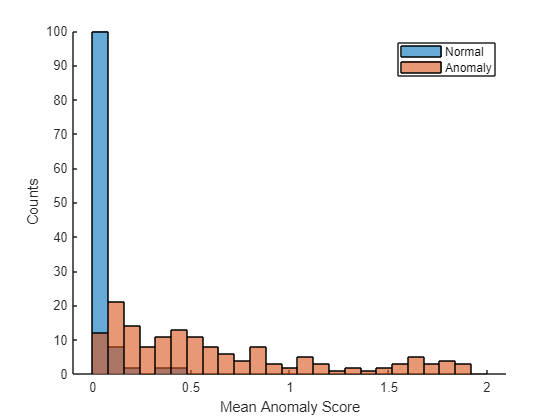

% Plot the distribution of anomaly scores for normal/anomalous images

numBins = 25; % Edit this value to show more or fewer bins
anomalyScoreXlim = 2; % Edit this value to zoom in on a smaller section of anomaly scores
edges = 0:anomalyScoreXlim/numBins:anomalyScoreXlim;
figure
hold on
hNormal = histogram(scores(labels==0),edges);
hAnomaly = histogram(scores(labels==1),edges);
hold off
legend([hNormal,hAnomaly],"Normal","Anomaly")
xlabel("Mean Anomaly Score")
ylabel("Counts")

% Manually select a new threshold value

detector.Threshold = 0.2

detector =   fcddAnomalyDetector with properties:

      Threshold: 0.2000
         Layers: [43×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'fcddHeadPseudoHuber'}
          State: [4×3 table]
     Learnables: [10×3 table]


## Re-Evaluate the Model

Now re-evaluate the model with this new threshold value. Has the recall increased? Do you think that this is an appropriate value for the given scenario, and balances high recall with satisfactory precision? If not, go back and adjust the threshold again to see if you can achieve better results.

testSetPredLabels = classify(detector,imdsTest);

% Calculate test set accuracy metrics again
testSetTrueLabels = imdsTest.Labels;
metrics = evaluateAnomalyDetection(testSetPredLabels,testSetTrueLabels,["Blood","Erosion", ...
    "Erythema","Foreign body","Polyp","Ulcer"]);

Evaluating anomaly detection results
------------------------------------
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    Precision    Recall     Specificity    F1Score    FalsePositiveRate    FalseNegativeRate
    ______________    ____________    _________    _______    ___________    _______    _________________    _________________

       0.84575          0.86615        0.97091     0.76724      0.96507      0.85714        0.034934              0.23276     



*Copyright 2024 The MathWorks, Inc.*